## Vehicular Platoons Coordination Simulator

This is the main file that one needs to execute to generate the results that we show in our paper.

clear all
close all
clc

rng(7)

Creation of the network of platoons

%% Setup
network_index = 0;                  % network Index
numOfPlatoons = 1;                  % num of platoons
numOfVehicles = [10]; %[4,5,6];            % num of vehicles in each platoon
totalNumOfVehicles = sum(numOfVehicles);

%% Initial setup
vehicleSeperationMean = 5;
vehicleSeperationVar = 2; 
platoonSeperationMean = 10;
platoonSeperationVar = 2;

%% Define the initial vehicular position/velocity/acceleration 
vehiclePosition = 0;                % Zeroth vehicle position
vehicleVelocity = 0;                % Zeroth vehicle velocity
vehicleAcceleration = 0;            % Zeroth vehicle acceleration

state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
desiredSeparation_ki = 0;              % Desired separation from the leader

%% Define the initial states and desired states for all the vehicles
for k = 1:1:numOfPlatoons           % for every platoon k
    
    parameters_k = [];
    noiseMean_k = [];
    noiseStd_k = [];
    states_k =  [];                       % initial states collection
    desiredSeperation_k = [];

    for i = 1:1:numOfVehicles(k)    % for every vehicle in the k-th platoon

        % Vehicle parameters (assumed homogenuous)
        mass_ki = 1500;
        length_ki = 2.5;
        Af_ki = 2.2;
        rho_ki = 0.78;
        Cd_ki = 0.35;
        Cr_ki = 0.067;
        tau_ki = 0.25;

        % Collection of the initial/initially desired states of each vehicle
        states_k = [states_k, state_ki];
        
        % Define the vehicle position/velocity/acceleration 
        vehiclePosition = vehiclePosition - vehicleSeperationMean - vehicleSeperationVar*(rand(1)-0.5);
        vehicleVelocity = 0;
        vehicleAcceleration = 0;
        state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
        

        % Desired vehicular positions 
        desiredSeperation_k = [desiredSeperation_k, desiredSeparation_ki];
        desiredSeparation_ki = desiredSeparation_ki + vehicleSeperationMean;

        % Collection of vehicle parameters
        vehicleParameters_i = [mass_ki; length_ki; Af_ki; rho_ki; Cd_ki; Cr_ki; tau_ki];
        parameters_k = [parameters_k, vehicleParameters_i];

        % Noise parameters
        noisemean_ki = rand(3,1);
        noisestd_ki = 0.1*rand(3,1);

        noiseMean_k = [noiseMean_k, noisemean_ki];
        noiseStd_k = [noiseStd_k, noisestd_ki];
            
    end
    
    vehiclePosition = states_k(1,end) - platoonSeperationMean - platoonSeperationVar*(rand(1)-0.5);
    
    state_ki = [vehiclePosition; vehicleVelocity; vehicleAcceleration];
    desiredSeparation_ki = 0;

    parameters{k} = parameters_k;
    states{k} = states_k;
    desiredSeparation{k} = desiredSeperation_k;
    noiseMean{k} = noiseMean_k;
    noiseStd{k} = noiseStd_k;
      
end

net = Network(network_index,numOfPlatoons,numOfVehicles,parameters,states,desiredSeparation,noiseMean,noiseStd);

Plotting the network of platoons

% Platoon simulation video figure setup
figure(1)
hold on 
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(1)

#### Synthesizing controllers for the platoon

**Configuration 1:** Centralized Stabilizing Control using Error Dynamics II

Note: Local passivating controller synthesis should not use a cost function in order to get a set of local controller gain coefficients that are smaller (and thus, practical).

% %%% Global controller synthesis specifications
% % Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
% errorDynamicsType = 2;  % Error dynamics formulation I or I
% isCentralized = 1;      % Centralized or decentralized controller synthesis
% isOnlyStabilizing = 1;  % Stabilizing controller or Disturbance robust Controller)
% gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar  % Desired max noise attenuation
% 
% %%% Local passivating controller synthesis specifications 
% % LowerBound on \nu and upperBound on \rho 
% nuBar = -10;        % For the constraint: nu >= nuBar       %nuBar = -8.1
% rhoBar = 5;         % For the constraint: rho <= rhoBar     %rhoBar = 4.1

**Configuration 2:** Centralized Robust Control using Error Dynamics II

Note: In the local passivating controller synthesis, when no cost function is used, the resulting passivity indices are not amenable to global controller synthesis. 

To resolve this, we can resort to using the fundamental cost function for local passicating controller synthesis. However, this leads to: (Issue 1) larger local controller gains, and (Issue 2) global controller gains with no inter-vehicle interconnections. 

To solve the first issue, we can resort to use a cost function (in local passivating controller synthesis) of the form: 0.0000001*(- nu + rhoBar); This leads to relatively low local controller gains as well as passivity indices that are amenable to global controller synthesis. However, (Issue 2) is still a problem. 

%%% Global controller synthesis specifications
% Error dynamics I/II, centralized/decentralized, stabilizing/robust, and upperBound on \gamma^2
errorDynamicsType = 2;  % Error dynamics formulation I or I
isCentralized = 0;      % Centralized or decentralized controller synthesis
isDSS = 1;               % Involve DSS constraints (1) or not (0)

isDSS = 1

isOnlyStabilizing = 0;  % Stabilizing controller or Disturbance robust Controller)
gammaSqBar = 10;        % For the constraint: gamma^2 <= gammaSqBar % Desired max noise attenuation

%%% Local passivating controller synthesis specifications 
% LowerBound on \nu and upperBound on \rho 
nuBar = -40;       % For the constraint: nuBar <= nu       
rhoBar = 15;       % For the constraint: rhoHat <= rho <= rhoBar

%%% Parameterized approach to co-design
%% Optimizing gammaSq with respect to the co-design parameters
pVals = net.optimizeCodesignParameters(isCentralized,isDSS)

PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.4223.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3462.
Global Synthesis Success with gammaSq=4.5603


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal =   -92.2917 -112.5028  -18.5414


R_i =   119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal =     0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal =     0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.4223.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3462.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=3.3018.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.6679.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2867.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.7332.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3061.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.1963.
Global Synthesis Success with gammaSq=3.7332


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=3.3018.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.6679.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2867.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.7332.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3061.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.1963.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=3.5213.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5576.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.09.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.3184.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.0359.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.1968.
Global Synthesis Success with gammaSq=4.0359


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=3.5213.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5576.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.09.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.3184.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.0359.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.1968.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.1143.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.4132.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3704.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1891.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.185.
Global Synthesis Success with gammaSq=4.1143


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.1143.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.4132.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3704.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1891.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.185.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.868.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5549.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.0054.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.4873.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3969.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.7496.
Global Synthesis Success with gammaSq=4.868


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.868.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5549.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.0054.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.4873.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3969.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.7496.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=4.0534.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.3732.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.8206.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.4092.
Global Synthesis Success with gammaSq=4.5603


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=4.0534.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.3732.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.8206.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.4092.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3047.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.6854.
Global Synthesis Success with gammaSq=4.5603


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3047.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.6854.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.9677.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.5601.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.5954.
Global Synthesis Success with gammaSq=4.5603


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.9677.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.5601.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.5954.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.8785.
Global Synthesis Success with gammaSq=4.5603


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.8785.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.4223.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.0407.
Global Synthesis Success with gammaSq=4.5603


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 1 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 2 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 3 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 4 with gammaSq=4.5603.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9618.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2142.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1919.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.4223.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.0407.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      10    4.560323e+00    0.000e+00    5.551e+07


PVal = 3×3
    0.1717   -0.1286   -0.0040
   -0.1286    0.1492   -0.1880
   -0.0040   -0.1880    1.0341


KVal = 1×3
    0.1458   -0.3289   -3.3435


LVal = 1×3
  -35.1345  -47.6453  -12.0323


R_i = 3×3
   38.1672   42.9138    7.9508
   42.9138   56.9416   10.5196
    7.9508   10.5196    2.9105


Decentralized Synthesis Success at: 1 with gammaSq=3.5561.


PVal = 3×3
    0.1286   -0.0998   -0.0015
   -0.0998    0.1161   -0.1564
   -0.0015   -0.1564    0.9962


KVal = 1×3
    0.1229   -0.2746   -3.9749


LVal = 1×3
  -44.8241  -58.7968  -13.2870


R_i = 3×3
   51.8224   56.6295    8.9672
   56.6295   72.8052   11.5137
    8.9672   11.5137    2.8246


Decentralized Synthesis Success at: 2 with gammaSq=3.2319.


PVal = 3×3
    0.1179   -0.0925   -0.0007
   -0.0925    0.1075   -0.1478
   -0.0007   -0.1478    0.9881


KVal = 1×3
    0.1132   -0.2568   -4.2055


LVal = 1×3
  -48.9306  -63.4433  -13.7825


R_i = 3×3
   57.5092   62.3760    9.3730
   62.3760   79.3624   11.9175
    9.3730   11.9175    2.8016


Decentralized Synthesis Success at: 3 with gammaSq=3.1461.


PVal = 3×3
    0.0170   -0.0151    0.0006
   -0.0151    0.0168   -0.0310
    0.0006   -0.0310    0.8092


KVal = 1×3
    0.0115   -0.0354  -16.9872


LVal = 1×3
 -256.8659 -291.7626  -31.9981


R_i = 3×3
  401.9329  387.7700   14.5856
  387.7700  438.1303   16.5255
   14.5856   16.5255    1.8591


Decentralized Synthesis Success at: 4 with gammaSq=3.459.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=4.1962.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2471.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.199.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.2461.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=7.0761.


PVal = 3×3
    0.1717   -0.1286   -0.0040
   -0.1286    0.1492   -0.1880
   -0.0040   -0.1880    1.0341


KVal = 1×3
    0.1458   -0.3289   -3.3435


LVal = 1×3
  -35.1345  -47.6453  -12.0323


R_i = 3×3
   38.1672   42.9138    7.9508
   42.9138   56.9416   10.5196
    7.9508   10.5196    2.9105


Decentralized Synthesis Success at: 1 with gammaSq=3.5561.


PVal = 3×3
    0.1286   -0.0998   -0.0015
   -0.0998    0.1161   -0.1564
   -0.0015   -0.1564    0.9962


KVal = 1×3
    0.1229   -0.2746   -3.9749


LVal = 1×3
  -44.8241  -58.7968  -13.2870


R_i = 3×3
   51.8224   56.6295    8.9672
   56.6295   72.8052   11.5137
    8.9672   11.5137    2.8246


Decentralized Synthesis Success at: 2 with gammaSq=3.2319.


PVal = 3×3
    0.1179   -0.0925   -0.0007
   -0.0925    0.1075   -0.1478
   -0.0007   -0.1478    0.9881


KVal = 1×3
    0.1132   -0.2568   -4.2055


LVal = 1×3
  -48.9306  -63.4433  -13.7825


R_i = 3×3
   57.5092   62.3760    9.3730
   62.3760   79.3624   11.9175
    9.3730   11.9175    2.8016


Decentralized Synthesis Success at: 3 with gammaSq=3.1461.


PVal = 3×3
    0.0170   -0.0151    0.0006
   -0.0151    0.0168   -0.0310
    0.0006   -0.0310    0.8092


KVal = 1×3
    0.0115   -0.0354  -16.9872


LVal = 1×3
 -256.8659 -291.7626  -31.9981


R_i = 3×3
  401.9329  387.7700   14.5856
  387.7700  438.1303   16.5255
   14.5856   16.5255    1.8591


Decentralized Synthesis Success at: 4 with gammaSq=3.459.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=4.1962.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.2471.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.199.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.2461.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=7.0761.
Global Synthesis Success with gammaSq=7.0761


PVal = 3×3
    0.0973   -0.0782   -0.0002
   -0.0782    0.0901   -0.1298
   -0.0002   -0.1298    0.9771


KVal = 1×3
    0.0990   -0.2292   -4.8218


LVal = 1×3
  -62.9454  -79.5158  -15.5101


R_i = 3×3
   75.3105   80.8579   10.7563
   80.8579  100.5363   13.3712
   10.7563   13.3712    2.8018


Decentralized Synthesis Success at: 1 with gammaSq=3.0582.


PVal = 3×3
    0.0823   -0.0671    0.0001
   -0.0671    0.0772   -0.1150
    0.0001   -0.1150    0.9547


KVal = 1×3
    0.0861   -0.2023   -5.4029


LVal = 1×3
  -72.7408  -90.5415  -16.5618


R_i = 3×3
   88.9895   94.2761   11.3513
   94.2761  115.6751   13.9291
   11.3513   13.9291    2.7247


Decentralized Synthesis Success at: 2 with gammaSq=6.2403.


PVal = 3×3
    0.0784   -0.0641    0.0002
   -0.0641    0.0737   -0.1110
    0.0002   -0.1110    0.9470


KVal = 1×3
    0.0822   -0.1944   -5.5774


LVal = 1×3
  -75.2467  -93.3512  -16.8178


R_i = 3×3
   92.7041   97.8066   11.4473
   97.8066  119.6536   14.0069
   11.4473   14.0069    2.6957


Decentralized Synthesis Success at: 3 with gammaSq=4.5062.


PVal = 3×3
    0.0418   -0.0352    0.0009
   -0.0352    0.0404   -0.0676
    0.0009   -0.0676    0.8491


KVal = 1×3
    0.0349   -0.1047   -8.4412


LVal = 1×3
 -113.8350 -136.6996  -20.7065


R_i = 3×3
  154.3728  155.2427   12.1982
  155.2427  184.7174   14.5448
   12.1982   14.5448    2.3230


Decentralized Synthesis Success at: 4 with gammaSq=4.289.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=6.6718.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.9358.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=9.323.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.9794.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.7243.


PVal = 3×3
    0.0973   -0.0782   -0.0002
   -0.0782    0.0901   -0.1298
   -0.0002   -0.1298    0.9771


KVal = 1×3
    0.0990   -0.2292   -4.8218


LVal = 1×3
  -62.9454  -79.5158  -15.5101


R_i = 3×3
   75.3105   80.8579   10.7563
   80.8579  100.5363   13.3712
   10.7563   13.3712    2.8018


Decentralized Synthesis Success at: 1 with gammaSq=3.0582.


PVal = 3×3
    0.0823   -0.0671    0.0001
   -0.0671    0.0772   -0.1150
    0.0001   -0.1150    0.9547


KVal = 1×3
    0.0861   -0.2023   -5.4029


LVal = 1×3
  -72.7408  -90.5415  -16.5618


R_i = 3×3
   88.9895   94.2761   11.3513
   94.2761  115.6751   13.9291
   11.3513   13.9291    2.7247


Decentralized Synthesis Success at: 2 with gammaSq=6.2403.


PVal = 3×3
    0.0784   -0.0641    0.0002
   -0.0641    0.0737   -0.1110
    0.0002   -0.1110    0.9470


KVal = 1×3
    0.0822   -0.1944   -5.5774


LVal = 1×3
  -75.2467  -93.3512  -16.8178


R_i = 3×3
   92.7041   97.8066   11.4473
   97.8066  119.6536   14.0069
   11.4473   14.0069    2.6957


Decentralized Synthesis Success at: 3 with gammaSq=4.5062.


PVal = 3×3
    0.0418   -0.0352    0.0009
   -0.0352    0.0404   -0.0676
    0.0009   -0.0676    0.8491


KVal = 1×3
    0.0349   -0.1047   -8.4412


LVal = 1×3
 -113.8350 -136.6996  -20.7065


R_i = 3×3
  154.3728  155.2427   12.1982
  155.2427  184.7174   14.5448
   12.1982   14.5448    2.3230


Decentralized Synthesis Success at: 4 with gammaSq=4.289.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=6.6718.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.9358.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=9.323.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=4.9794.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.7243.
Global Synthesis Success with gammaSq=9.323


PVal = 3×3
    0.0768   -0.0629    0.0002
   -0.0629    0.0723   -0.1093
    0.0002   -0.1093    0.9435


KVal = 1×3
    0.0805   -0.1911   -5.6533


LVal = 1×3
  -76.2936  -94.5249  -16.9238


R_i = 3×3
   94.2821   99.2941   11.4809
   99.2941  121.3311   14.0322
   11.4809   14.0322    2.6827


Decentralized Synthesis Success at: 1 with gammaSq=3.0355.


PVal = 3×3
    0.0693   -0.0571    0.0004
   -0.0571    0.0657   -0.1011
    0.0004   -0.1011    0.9263


KVal = 1×3
    0.0720   -0.1751   -6.0400


LVal = 1×3
  -81.3681 -100.2179  -17.4323


R_i = 3×3
  102.1072  106.5921   11.5998
  106.5921  129.5774   14.1079
   11.5998   14.1079    2.6156


Decentralized Synthesis Success at: 2 with gammaSq=3.0261.


PVal = 3×3
    0.0674   -0.0556    0.0004
   -0.0556    0.0639   -0.0990
    0.0004   -0.0990    0.9216


KVal = 1×3
    0.0697   -0.1708   -6.1509


LVal = 1×3
  -82.7838 -101.8072  -17.5732


R_i = 3×3
  104.3242  108.6458   11.6241
  108.6458  131.9018   14.1201
   11.6241   14.1201    2.5966


Decentralized Synthesis Success at: 3 with gammaSq=3.0227.


PVal = 3×3
    0.0492   -0.0411    0.0008
   -0.0411    0.0472   -0.0771
    0.0008   -0.0771    0.8713


KVal = 1×3
    0.0449   -0.1249   -7.5908


LVal = 1×3
 -101.0991 -122.4127  -19.4530


R_i = 3×3
  133.4744  135.5786   11.8770
  135.5786  162.4732   14.2546
   11.8770   14.2546    2.3984


Decentralized Synthesis Success at: 4 with gammaSq=11.01.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.6585.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3169.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.9561.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.6799.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3119.


PVal = 3×3
    0.0768   -0.0629    0.0002
   -0.0629    0.0723   -0.1093
    0.0002   -0.1093    0.9435


KVal = 1×3
    0.0805   -0.1911   -5.6533


LVal = 1×3
  -76.2936  -94.5249  -16.9238


R_i = 3×3
   94.2821   99.2941   11.4809
   99.2941  121.3311   14.0322
   11.4809   14.0322    2.6827


Decentralized Synthesis Success at: 1 with gammaSq=3.0355.


PVal = 3×3
    0.0693   -0.0571    0.0004
   -0.0571    0.0657   -0.1011
    0.0004   -0.1011    0.9263


KVal = 1×3
    0.0720   -0.1751   -6.0400


LVal = 1×3
  -81.3681 -100.2179  -17.4323


R_i = 3×3
  102.1072  106.5921   11.5998
  106.5921  129.5774   14.1079
   11.5998   14.1079    2.6156


Decentralized Synthesis Success at: 2 with gammaSq=3.0261.


PVal = 3×3
    0.0674   -0.0556    0.0004
   -0.0556    0.0639   -0.0990
    0.0004   -0.0990    0.9216


KVal = 1×3
    0.0697   -0.1708   -6.1509


LVal = 1×3
  -82.7838 -101.8072  -17.5732


R_i = 3×3
  104.3242  108.6458   11.6241
  108.6458  131.9018   14.1201
   11.6241   14.1201    2.5966


Decentralized Synthesis Success at: 3 with gammaSq=3.0227.


PVal = 3×3
    0.0492   -0.0411    0.0008
   -0.0411    0.0472   -0.0771
    0.0008   -0.0771    0.8713


KVal = 1×3
    0.0449   -0.1249   -7.5908


LVal = 1×3
 -101.0991 -122.4127  -19.4530


R_i = 3×3
  133.4744  135.5786   11.8770
  135.5786  162.4732   14.2546
   11.8770   14.2546    2.3984


Decentralized Synthesis Success at: 4 with gammaSq=11.01.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.6585.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.3169.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.9561.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.6799.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3119.
Global Synthesis Success with gammaSq=11.01


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.0652.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3452.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.2541.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.0652.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3452.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.2541.
Global Synthesis Success with gammaSq=4.1989


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.1117.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.
Global Synthesis Success with gammaSq=3.1117


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.1117.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=3.3684.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5187.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.245.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2201.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.
Global Synthesis Success with gammaSq=3.5187


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=3.3684.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.5187.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.245.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2201.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.7933.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1502.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2309.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3037.
Global Synthesis Success with gammaSq=3.7933


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=3.7933.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1502.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2309.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3037.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=3.1283.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9114.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.4311.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2476.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.6178.
Global Synthesis Success with gammaSq=4.4311


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=3.1283.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.9114.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.4311.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.2476.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.6178.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.179.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Failed at: 6.
Global Synthesis Failed


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=3.179.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Failed at: 6.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.471.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.6757.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3387.
Global Synthesis Success with gammaSq=3.6757


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.471.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.6757.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.3387.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1469.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.1783.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.
Global Synthesis Success with gammaSq=4.1989


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.1469.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.1783.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=2.9946.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.0652.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Failed at: 8.
Global Synthesis Failed


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.0652.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Failed at: 8.


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


R_i = 3×3
  111.2393  115.0366   11.6853
  115.0366  139.1447   14.1452
   11.6853   14.1452    2.5396


Decentralized Synthesis Success at: 3 with gammaSq=3.0112.


PVal = 3×3
    0.0529   -0.0440    0.0007
   -0.0440    0.0506   -0.0817
    0.0007   -0.0817    0.8822


KVal = 1×3
    0.0502   -0.1348   -7.2339


LVal = 1×3
  -96.3050 -117.0225  -18.9627


R_i = 3×3
  125.7402  128.3943   11.7926
  128.3943  154.3198   14.1919
   11.7926   14.1919    2.4387


Decentralized Synthesis Success at: 4 with gammaSq=2.9764.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 5 with gammaSq=2.9946.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 6 with gammaSq=4.1989.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 7 with gammaSq=3.0652.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 8 with gammaSq=3.3452.


PVal = 3×3
    0.0566   -0.0470    0.0006
   -0.0470    0.0541   -0.0863
    0.0006   -0.0863    0.8933


KVal = 1×3
    0.0555   -0.1447   -6.9165


LVal = 1×3
  -92.2917 -112.5028  -18.5414


R_i = 3×3
  119.2652  122.4289   11.7388
  122.4289  147.5351   14.1610
   11.7388   14.1610    2.4786


Decentralized Synthesis Success at: 9 with gammaSq=3.1819.
Global Synthesis Success with gammaSq=4.1989


PVal = 3×3
    0.0666   -0.0549    0.0004
   -0.0549    0.0632   -0.0981
    0.0004   -0.0981    0.9196


KVal = 1×3
    0.0687   -0.1690   -6.1984


LVal = 1×3
  -83.3897 -102.4874  -17.6333


R_i = 3×3
  105.2751  109.5260   11.6339
  109.5260  132.8984   14.1247
   11.6339   14.1247    2.5886


Decentralized Synthesis Success at: 1 with gammaSq=3.0212.


PVal = 3×3
    0.0629   -0.0520    0.0005
   -0.0520    0.0599   -0.0938
    0.0005   -0.0938    0.9103


KVal = 1×3
    0.0640   -0.1606   -6.4346


LVal = 1×3
  -86.3796 -105.8465  -17.9317


R_i = 3×3
  109.9677  113.8645   11.6765
  113.8645  137.8138   14.1428
   11.6765   14.1428    2.5500


Decentralized Synthesis Success at: 2 with gammaSq=3.0134.


PVal = 3×3
    0.0620   -0.0513    0.0005
   -0.0513    0.0590   -0.0927
    0.0005   -0.0927    0.9078


KVal = 1×3
    0.0628   -0.1583   -6.5013


LVal = 1×3
  -87.1953 -106.7659  -18.0160


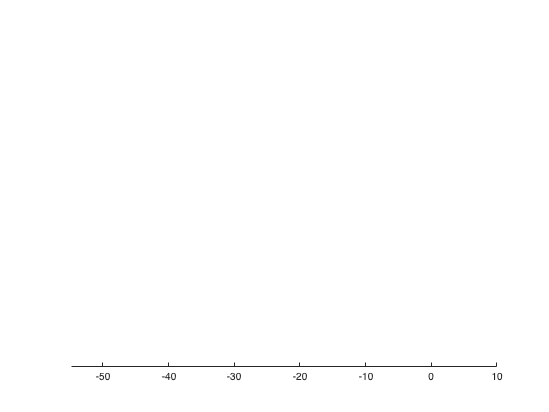


%% Resulting optimal parameters for Centralized case
% pVals = [0.0053    0.0451    0.0444    0.0453    0.0450] % after all tweaks (centralized)
%% Resulting optimal parameters for Decentralized case
% pVals = [0.1995    0.1282    0.2070    0.1636    0.2022] % after all tweaks (centralized)

%% An alternative: Trying some fixed set of parameters.
% pVals = 0.15*ones(numOfPlatoons,max(numOfVehicles));
%% Some other alternatives:
% pVals = [0.0203    0.0203    0.0202    0.0202    0.0204] % with initial condition 0.15
% pVals = [0.0029    0.0029    0.0028    0.0029    0.0029] % with initial condition 0.1


%%% Execution of the controller synthesis
%net.platoons(1).vehicles(2).synthesizeLocalControllers(2,nuBar,rhoBar)
% Actually, above defined nuBar,rhoBar,gammaSqBar are no longer needed

net.loadPlatoonControllers(errorDynamicsType,isCentralized,isDSS,isOnlyStabilizing,gammaSqBar,nuBar,rhoBar,pVals);

%%% In decentralized implementation, there are two things to consider:
% gammaSq_i needs to be costrainted at each subsystem i (or penalized considerably), 
% otherwise it tends to grow with i. Recall that max(gammaSq_i) = gammaSq. 
% There is a zero eigenvalue in the main LMI constraint (this is also in the
% centralized problem). This may be the reason why solver gives "Unknown Status" error.

%%% Graphing the Resulting topology
figure(2)
hold on
ax1 = gca;                   % gca = get current axis handle
ax1.YAxis.Visible = 'off';   % hide out the y-axis from the plot
% axis off
% set(gcf,'Visible','off')
net.drawNetwork(2)

Running the Simulation - Updating the states

% Update the states and plot them in real time as an animation
dt = 0.01;
tMax = 10; 
tArray = 0:dt:tMax;

% Leader's trajectory specification
tVals = tMax*[0,0.2,0.4,0.6,0.8,1];     % Special time instants (inbetween which the acceleration is constant)
vVals = [0,30,40,40,20,20];  % Velocities to be achived at these time instants
net.generateLeadersControlProfiles(dt,tVals,vVals);

% Updating the platoons
for t = tArray

    % Use this update function to achieve the update of the entire program
    net.update(t,dt);
    net.redrawNetwork(2)
    pause(0.01)
    
end

% Plot the state histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

% Plot the location error histories
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{x}(t)$/location-error(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

figure
hold on
for k = 1:1:numOfPlatoons
    for i = 2:1:numOfVehicles(k)
        plot(tArray,net.platoons(k).vehicles(i).errorHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$\tilde{v}(t)$/velocity-error(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


% Plot the state histories of leaders
figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(1,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$x(t)$/distances(m)','Interpreter','latex')
legend(Location="eastoutside")
grid on 


figure
hold on
for k = 1:1:numOfPlatoons
    for i = 1
        plot(tArray,net.platoons(k).vehicles(i).stateHistory(2,:)','-',DisplayName=['Plat:',num2str(k),'; Vehi:',num2str(i)]);
    end
end
xlabel('$t$/time(s)','Interpreter','latex')
ylabel('$v(t)$/speed(m/s)','Interpreter','latex')
legend(Location="eastoutside")
grid on 

Ideas to pursue next:

What is the best set of passivity information for this topology synthesis?

Leader's connection design (Centralized Setting, ED-I)

For the case with z = C e

Local controller design for passivation